% Script, Start Sim file.  Initialize variables

% Parameters used in the design.

% Fixed by FPGA fabric or hardware architecture
FFT_Size = 8192;            % Fixed in design.  Placed here so that subsequent calculations can be made from this number.
Sample_Freq = 166666666;

% User editable parameters
PolyphaseFactor = 4;        % Control size of the polyphase filter.  If Polyphase factor = 4, then filter is 4*FFT_Size in length

% Calculated based on the design construction.
Filter_Size = PolyphaseFactor*FFT_Size;
FFT_Padding = 100; 
Sample_Period_ns = 1/Sample_Freq*1e9;
Clock_Count_Per_FFT = Filter_Size+FFT_Padding; 
Num_FFT_Per_S = floor((Sample_Freq)/Clock_Count_Per_FFT/500)*500;
PPS_Period = Sample_Freq;

% LowPassFilter;


% Bit accurate simulation of FFT/Polyphase performance

Tones   = [ 30.1,  50];    % Tone center frequency
ToneAmp = [ .25, .125];    % Amplitude of each tone

NoiseAmp = .000025;                 % Amplitudde of the noise
%NoiseAmp = [.25, .025, .0025, 0];                 % Amplitudde of the noise

FrequencyScale = ((1:FFT_Size)*Sample_Freq/FFT_Size/1e6)';

%NumSamplesPerSecond = 3000;
NumSamplesPerSecond = Num_FFT_Per_S;

% C simulation constants
generics.C_NFFT_MAX = 13;
generics.C_ARCH = 3;
generics.C_HAS_NFFT = 1;
generics.C_USE_FLT_PT = 0;
generics.C_INPUT_WIDTH = 32;
generics.C_TWIDDLE_WIDTH = 25;
generics.C_HAS_SCALING = 1; % Set to 0 if C_USE_FLT_PT = 1
generics.C_HAS_BFP = 0;
generics.C_HAS_ROUNDING = 1;
% Scaling schedule
scaling_sch0 = 1;
scaling_sch1 = 2;
scaling_sch2 = 2;
scaling_sch3 = 2;
scaling_sch4 = 2;
scaling_sch5 = 2;
scaling_sch6 = 2;
scaling_sch = [scaling_sch6, scaling_sch5, scaling_sch4, scaling_sch3, scaling_sch2, scaling_sch1, scaling_sch0];

FreqIndex = (1:Filter_Size);

ntBP = numerictype(1,32,31);                % Define numberic type as signed, 32 bit, binary point at 31

dB_ThreeTone_Noise = zeros(length(NoiseAmp),FFT_Size);

FFT_Out = zeros(FFT_Size,1);
SecondSum = zeros(FFT_Size,1);
Third_Sum = zeros(Filter_Size,1);

fprintf('\n');

for Count1 = 1:length(NoiseAmp)
    for Count2 = 1:NumSamplesPerSecond
        SignalInput = (rand(Filter_Size,1)-.5)*2*NoiseAmp(Count1);
%        SignalInput = DataInput.signals.values(((Count2-1)*Filter_Size+1):Filter_Size*Count2);
         StartPhase = rand(1,length(Tones))*2*pi;
         for Count3 = 1:length(Tones)
             SignalInput = SignalInput + sin(StartPhase(Count3) + FreqIndex' * 2*pi/(Sample_Freq/1e6/Tones(Count3)))*ToneAmp(Count3);
         end
         
         %Quantize the data in 16 bit space
         SignalInput = floor(SignalInput*16384-8192);
         Third_Sum = Third_Sum + SignalInput;
         
%          SignalInput = SignalInput .* FilterPrototype;

         SignalInput = sum(reshape(SignalInput, FFT_Size, []),2);
         SignalInput = SignalInput /(max(abs(SignalInput))+.000001);

        fft_ba = fft(SignalInput, FFT_Size);
        FFT_Out = FFT_Out + fft_ba;
        Second_Sum = SecondSum + SignalInput;

        if Count2/100 == floor(Count2/100)
            fprintf('.');
        end

        if Count2/1000 == floor(Count2/1000)
            fprintf('\n');
        end
    end
    dB_ThreeTone_Noise(Count1,:) = 10*log10(FFT_Out/max(FFT_Out));
end

..........

..........

..........

..........

..........

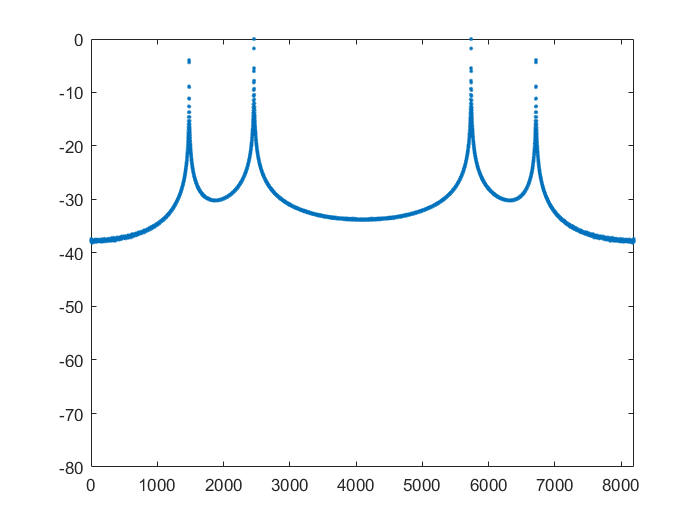


Second_FFT = fft(Second_Sum, FFT_Size);

% Third_Sum = Third_Sum .* FilterPrototype;
Third_Sum = sum(reshape(Third_Sum, FFT_Size, []),2);

Third_FFT= fft(Third_Sum,FFT_Size);



figure;
plot(10*log10(abs(Third_FFT)/max(abs(Third_FFT(10:end)))),'.');
axis([0 8192 -80 0]);

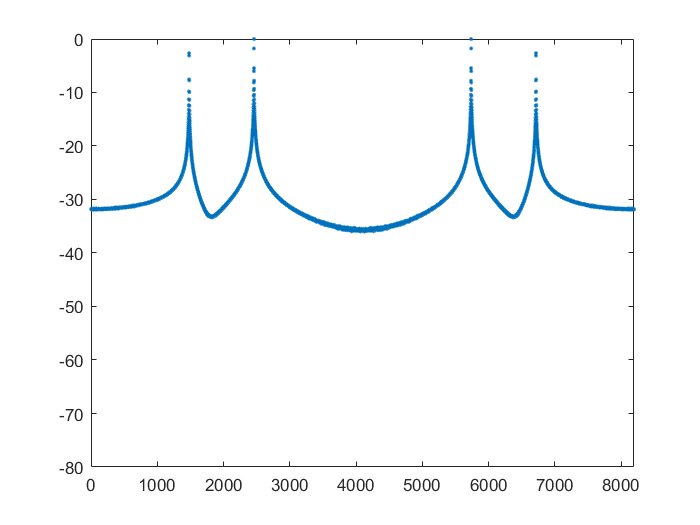


figure;
plot(10*log10(abs(Second_FFT)/max(abs(Second_FFT(10:end)))),'.');
axis([0 8192 -80 0]);

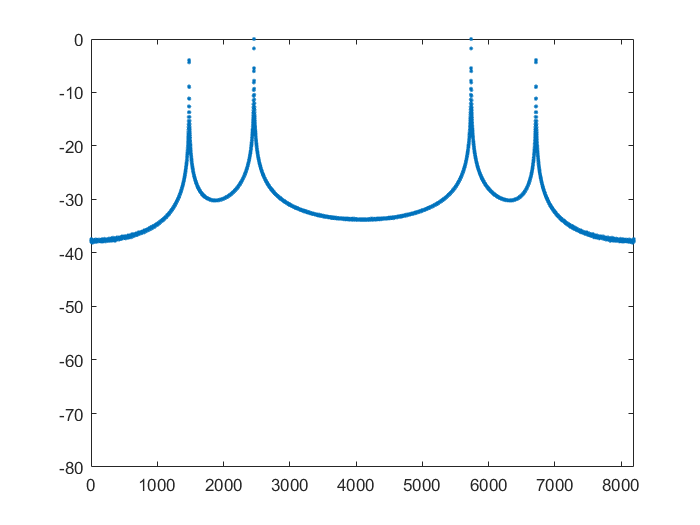


figure; 
plot(10*log10(abs(FFT_Out)/max(abs(FFT_Out(10:end)))),'.');
axis([0 8192 -80 0]);



% 
% plot(FrequencyScale,dB_ThreeTone_Noise(1,:),'.')
% 
% plot(FrequencyScale,dB_ThreeTone_Noise(1,:),'.', FrequencyScale,dB_ThreeTone_Noise(2,:),'.', FrequencyScale,dB_ThreeTone_Noise(3,:),'.', FrequencyScale,dB_ThreeTone_Noise(4,:),'.')
% ylabel('Relative amplitude (dB)');
% xlabel('Frequency (MHz)');
% title('Comparison of different noise levels given constant tone inputs');
% legend({sprintf('Three tones, noise at %0.4f full scale', NoiseAmp(1)), ...
%         sprintf('Three tones, noise at %0.4f full scale', NoiseAmp(2)), ...
%         sprintf('Three tones, noise at %0.4f full scale', NoiseAmp(3)), ...
%         sprintf('Three tones, No noise input')                              });